# Shooting method finding eigenvalues for 4th order ODE

We have following ODE:    $\frac{d^4 y}{{\textrm{dx}}^4 }-\left(\frac{\lambda }{x^4 }\right)y\;\;=\;0$      .... 1 < x < e

with boundary conditions as:     $\begin{array}{l}
y\left(1\right)=0\;,\;\frac{\textrm{dy}}{\textrm{dx}}\left(1\right)=0\\
y\left(e\right)=0\;,\;\frac{\textrm{dy}}{\textrm{dx}}\left(e\right)=0
\end{array}$

[This problem is solved in research paper of same name by D.J.Jones (1993)]

We could convert this two point BVP into IVP and solve it using shooting method, but the problem is that we don't know the value of $\lambda$, for which the equation would match the boundary condition. The values that fit there, are called eigenvalues and problem of finding them is called Eigenvalue problem.

clear; clc; close all;      % clears everything

### Defining Boundary conditions for Shooting method

Since the equation is of 4th order, we need 4 boundary conditions on starting point, but we only have 2. So, as per the reason described in the paper, we choose y'''(1) = 0.1 and use y''(1) as guess. This doesn't change the eigenvalues.

e = 2.718281828459;
xValues = [1 e];        % Domain length
y_St = 0;               % y at start
yD_St = 0;              % y' at start
yDD_St_Gs = -0.1;      % y'' at start (Guess value)
yDDD_St = 0.1;          % y''' at start

### Solving

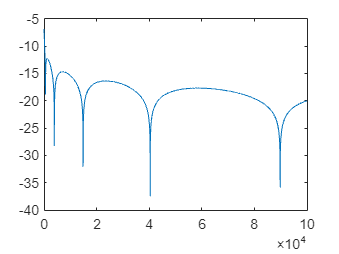


lambda = 0:20:100000;
s = zeros(1,length(lambda));
for l = 1:length(lambda)
    tempFunc = @(abc) odeSolve(xValues, y_St, yD_St, abc, yDDD_St,lambda(l));
    yDD_St_Final = fzero(tempFunc, yDD_St_Gs);
    s(l) = odeSolve2(xValues, y_St, yD_St, yDD_St_Final, yDDD_St,lambda(l));
end

plot(lambda,log(s));

eigVal = findLocalMin(lambda,s);
disp(['Eigen Values are: ',num2str(eigVal)]);

Eigen Values are: 540   3920  14860  40360  89760


### ODE Definition

The Original ODE to be modelled is: $\frac{d^4 y}{{\textrm{dx}}^4 }-\left(\frac{\lambda }{x^4 }\right)y\;\;=\;0$ 

**Input:**

1) x & lamb:- value of dependent variable x and lambda

2) XV:- Values of x in domain

2) Y:- Column vector representing the boundary conditions at x = 1

- 
$${\left\lbrack \;y\;\;;\;\frac{\textrm{dy}}{\textrm{dx}}\;;\;\frac{d^2 y}{{\textrm{dx}}^2 }\;\;;\;\frac{d^3 y}{{\textrm{dx}}^3 }\right\rbrack }_{x\;=1}$$


**Output:**

dYdx: column vector, representing higher order ODE as a system of 1st order ODEs. (pay attention to capital 'Y' in dYdx)


$$\frac{{\textrm{dy}}_1 }{\textrm{dx}}=y_2 \;\;\;\;\;;\;\;\;\frac{dy_2 }{\textrm{dx}}=y_3 \;\;\;\;\;;\;\;\;\;\;\frac{{\textrm{dy}}_3 }{\textrm{dx}}=y_4 \;\;\;\;;\;\;\;\;\;\;\frac{{\textrm{dy}}_4 }{\textrm{dx}}=\left(\frac{\lambda }{x^4 }\right)y_1$$


function resi = odeSolve(XV, bc1, bc2, bc3, bc4, lamb)
    Y = [bc1;bc2;bc3;bc4];
    [~,b] = ode45(@odedef, XV, Y);
    resi = b(end,1) + b(end,2);
    function dYdx = odedef(x,Y)
        y = Y(1);
        dydx = Y(2);
        d2ydx2 = Y(3);
        d3ydx3 = Y(4);
        dYdx(1,1) = dydx;
        dYdx(2,1) = d2ydx2;
        dYdx(3,1) = d3ydx3;
        dYdx(4,1) = (lamb/(x^4))*y;
    end
end

function resi = odeSolve2(XV, bc1, bc2, bc3, bc4, lamb)
    Y = [bc1;bc2;bc3;bc4];
    [~,b] = ode45(@odedef, XV, Y);
    resi = b(end,1)^2 + b(end,2)^2;
    function dYdx = odedef(x,Y)
        y = Y(1);
        dydx = Y(2);
        d2ydx2 = Y(3);
        d3ydx3 = Y(4);
        dYdx(1,1) = dydx;
        dYdx(2,1) = d2ydx2;
        dYdx(3,1) = d3ydx3;
        dYdx(4,1) = (lamb/(x^4))*y;
    end
end